## Introduction

Any EEG signal is basically composed of the measured signal from the brain region of interest, signal measured due to the activity of other brain regions (source mixing), and noise. 

To build a realistic EEG simulation step by step, 

- we first model the clean activity of a single region—starting with a **single sine wave** (Module 1), 

- and then combining frequencies into a **complex wave** (Module 2),

-  before adding **source mixing** (Module 3) 

- and **noise**.

- for all the modules, the phase shift is considered to be zero, which is different from real data. here we are just trying to make it as simple as possible. 

According to Fourier theorem, any complex signal can be represented as weighted sums of sinusoids (sines and cosines), that's why we are going to simulate single sin wave before   simulating a complex wave.  

## module 1

first, we need to simulate the data we are going to analyze later. 

this simulation process is important since it's giving us the ground truth to evaluate our analysis method.

quick summary of the steps we are going to follow:

- simulate a single sine wave

- simulate a complex wave of 2 sine waves

- simulate complex wave of x number of waves. (frequency f and amplitudes amps are fixed). 

- this can represent one simple EEG electrode+ noise.

### 1. simulate single sine wave

for any sine wave you need to describe, you have to tell what is the **frequency**, **duration**, and the** amplitude** + the** phase** (we will skip it for this part for simplification). 

**quick note: **

when you are changing an analogue signal(real world signal) to digital one, so, you need to define the suitable sampling rate( how many time points to set per second). This Sampling Frequency (srate) is chosen depending on **Nyquist theorem** that shows that you need to choose your sampling frequency to be larger than the double of the analogue (real) wave frequency. if your analogue wave is 10 your sampling rate should be over 20. 

sampling_frequency = 50;
step = 1/sampling_frequency;
%duration 2 sec 
dur= 2;
%time vector = start: step: end 
% start from 0 and end = duration - one step, if you  start from first step the end will be dur 
t1=0:step:dur-step;
n = length(t1);
%simulated wave frequency
f_alpha = 10;



sine wave is describes as:

wave= a*sin(2*pi*f*t)

a: amplitude, f: frequency,  t: time 

(2*pi*f*t) converts frequency in {Hz} into **angular frequency **in radians per second, since trigonometric functions in math and MATLAB expect radians

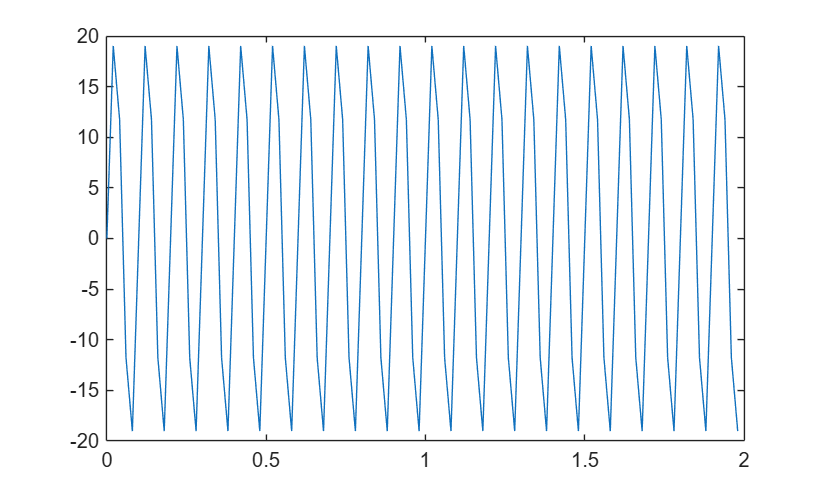

%final simulated wave 
alpha = 20* sin(2*pi*f_alpha*t1);
plot(t1,alpha)

### 2. simulate complex wave of 2 sine waves

%use the same time vector, define the frequency and the amp =80
f_delta = 2;
delta = 80* sin(2*pi*f_delta*t1);

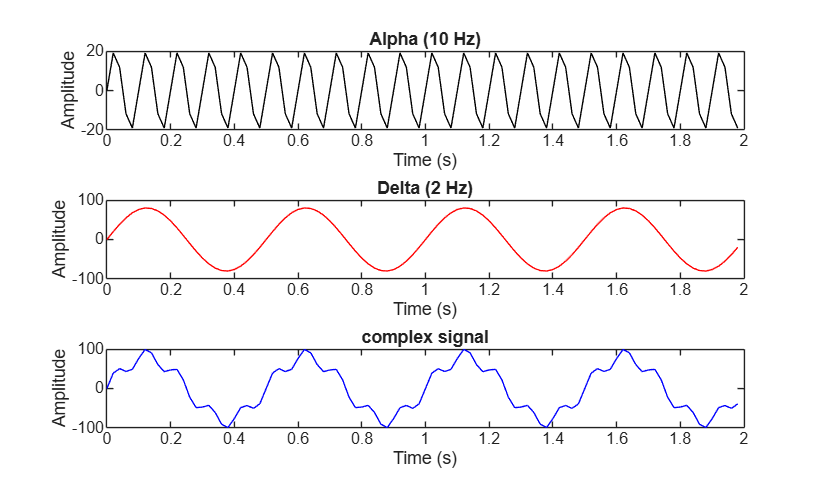


%generate your mixed signal by adding all together.
mixed = alpha+ delta;
figure;

subplot(3,1,1);
plot(t1, alpha, 'k');
title('Alpha (10 Hz)');
xlabel('Time (s)');
ylabel('Amplitude')

subplot(3,1,2);
plot(t1, delta,'r');
title('Delta (2 Hz)');
xlabel('Time (s)');
ylabel('Amplitude')

subplot(3,1,3);
plot(t1, mixed, 'b');
title('complex signal');
xlabel('Time (s)');
ylabel('Amplitude')

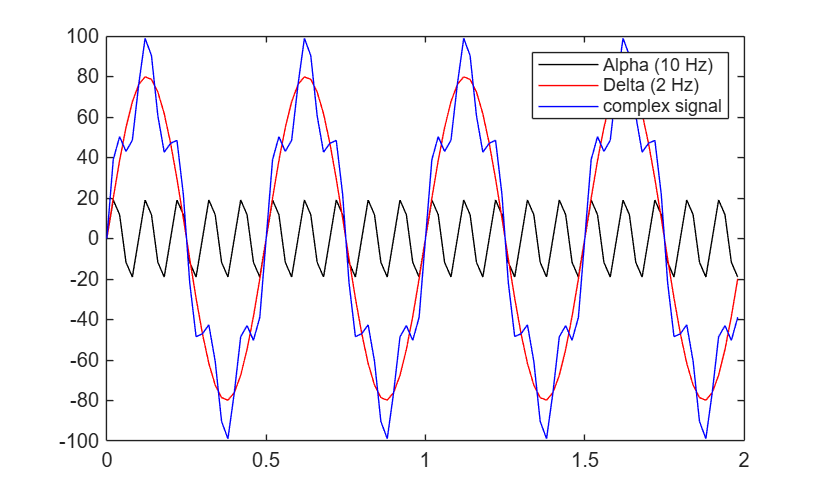


%to plot all of them on the same figure
figure
plot(t1, alpha, 'k', t1, delta,'r',t1, mixed, 'b' );
legend('Alpha (10 Hz)','Delta (2 Hz)','complex signal');

## simulate complex wave of 5 waves. 

for bigger numbers you can't generate each wave separately. 

in this step we will try to use loops to generate our waves, but for better visualizations we are going to use fixed number of frequencies and amplitudes. 

Note:

For now, we're using a fixed set of frequencies to keep things simple. Once you move to a more realistic simulation, you'll let the frequencies change from trial to trial since the brain doesn't hit the exact same frequency on every single trial.

f = [10,15,20,30,35];
amp = [5,  3.5, 2.5, 1.5, 1];

from the equation

 wave = a.sin(2*pi*f*t)

we have the amplitudes and frequencies. you can generate 5 waves using for loop, but what about t?

as we mentioned before, you need to determine the **sampling rate**, and **duration** to get your time vector.  

srate = 90; 
t2=0:1/srate:5-1/srate; %assuming that the duration of the signal is 5 sec



note: 

as we need to see all the generated waves, we will add figure function before the loop.

 BE CAREFUL, if you don't add it you will not be able to see the waves as the loop will give the result of the last iteration only.

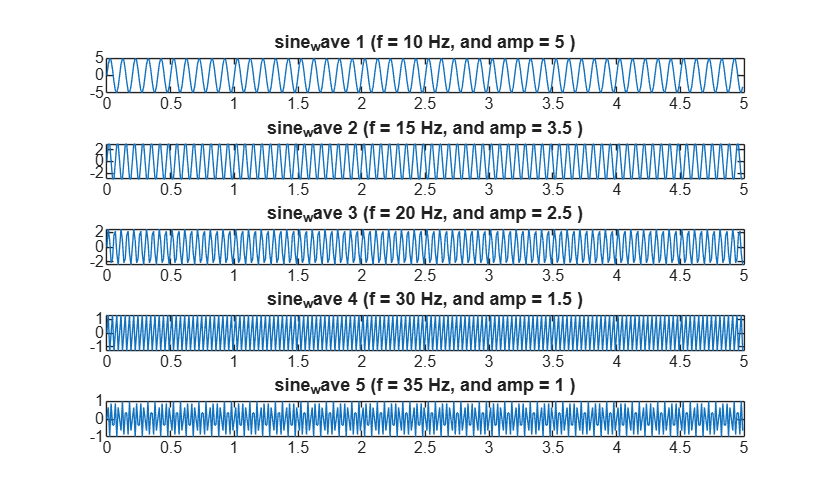

complex_wave = zeros(size(t2)); %empty vector to assign your simulated waves to it
figure
for i = 1: length(f)
    sine_wave =  amp(i)* sin(2*pi*f(i)*t2); 
    subplot(length(f), 1, i)
    plot(t2, sine_wave)
    title(['sine_wave ' num2str(i) ' (f = ' num2str(f(i)) ' Hz,' ' and amp = ' num2str(amp(i)) ' )'])
end

now you have your 5 waves, with their amplitudes and frequencies known. 

in previous step we needed to plot all the waves separately, but real brain waves are complex waves from different regions. as a result I need to add all of them together.

so, if you are expecting the code to be like this, 

for i = 1 : length(f)

    complex_wave = amp(i)* sin(2*pi*f(i)*t) ,

end

that means for every iteration you are losing the previous wave

how to fix?

inside your loop, you will update the value of your complex_wave variable.  so for every iteration you are going to add the previous value to your wave to generate a complex wave 

our equation to be like:

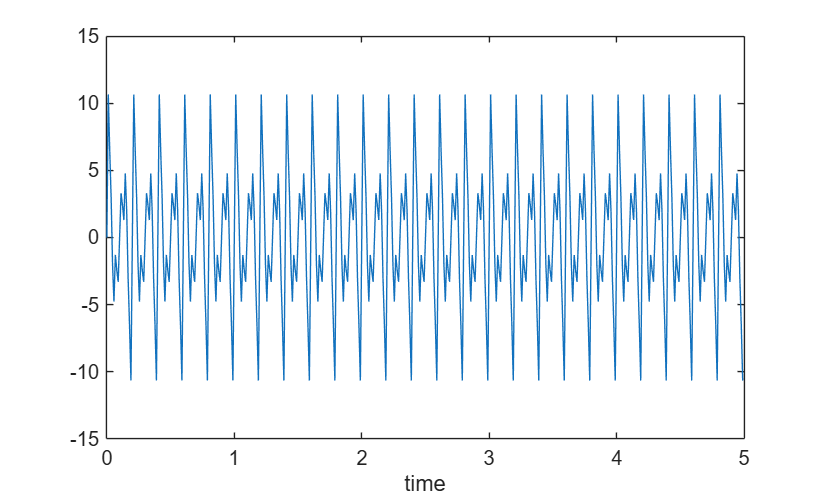

for i = 1: length(f)
    complex_wave = complex_wave + amp(i)* sin(2*pi*f(i)*t2);     
end
figure;
plot(t2,complex_wave)
xlabel('time')

#### noise generation

we have different types of noise, for now we will generate a white noise.

 use randn function for generating noise as random numbers normally distributed, then multiply by .5 to reduce the standard deviation of it to the half so you can avoid the large effect of  noise

noise1 = .5 * randn(size(t2));
complex_wave_1 = complex_wave+ noise1;

## this can represent one simplified EEG electrode.  

**important note: **all examples included in this module are simplified, it's not similar to the complexity of real EEG signal as EEG signal is a mixture of waves from different resources in the brain, not simple wave. therefor, we are simulating waves using fixed numbers just for simplicity.

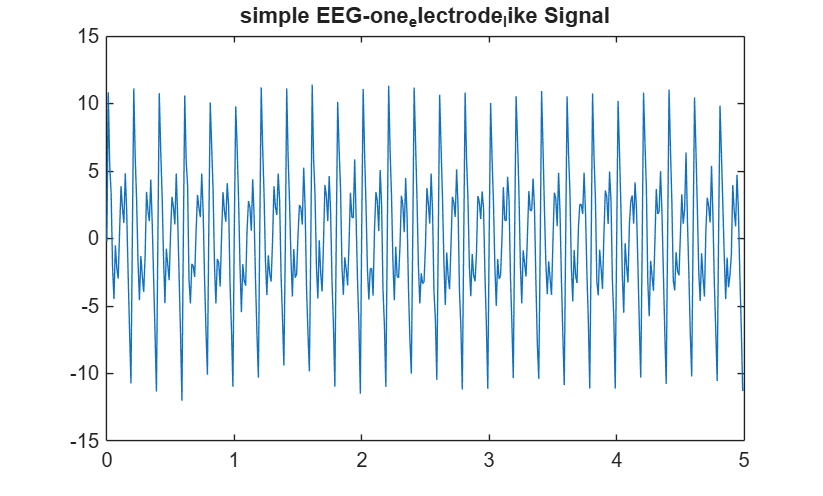

figure
plot(t2, complex_wave_1 )
title('simple EEG-one_electrode_like Signal');

that could be similar to ONLY one line of EEG graph representing a complex wave of one electrode. 